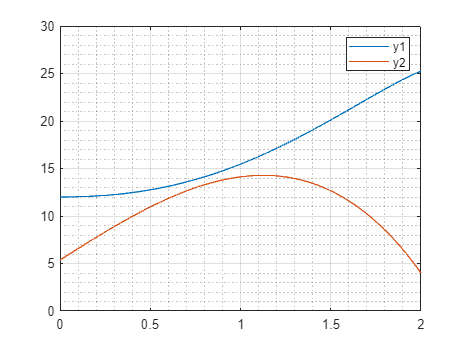

clear;clc;close all; % clean up
%23
% defining the x-grid:
nr_of_points=100;
x_start = 0;
x_end = 1;
x=linspace(0,2,100);
% function y1: a boundary value is given at the left side (at x=x_start)
global y1_left; y1_left = 12;
% function y2: a boundary value is given at the right end (at x= x_end)
global y2_right; y2_right = 4;
% init guess: e take the boundary values as init-guess :
y_init=[y1_left; y2_right]; initguess=bvpinit(x,y_init);
% calling the solver:
sol=bvp4c(@MyODESys,@bfunction,initguess);
% graphical representation:
plot(sol.x, sol.y(1,:), sol.x, sol.y(2,:));
legend('y1','y2');grid on; grid minor;

function dy = MyODESys(x,y)
dy=zeros(2,1);
dy(1)= 2*x * y(2)^(1/2);
dy(2)= -13*x^2 + y(1);
end
function res=bfunction(y1_b,y2_b)
global y1_left; global y2_right;
res=[y1_b(1) - y1_left;y2_b(2) - y2_right];
end